clc
clear
close all

robot = rigidBodyTree('DataFormat', 'column');

body = rigidBody('body1');

jnt = rigidBodyJoint('jnt1', 'revolute');
jnt.JointAxis = [0 0 1];
jnt.HomePosition = pi/4; % User defined joint value offset
tform = trvec2tform([0.2, 0.2, 0]); % User defined frame offset
setFixedTransform(jnt, tform);
body1.Joint = jnt;

addBody(robot, body, 'base'); % Add body1 to base

body = rigidBody('body2');
jnt = rigidBodyJoint('jnt2', 'revolute');
jnt.JointAxis = [0 0 1];
jnt.HomePosition = pi/6; % User defined joint value offset
tform = trvec2tform([1, 0, 0]); % User defined frame offset
setFixedTransform(jnt, tform);
body.Joint = jnt;
addBody(robot, body, 'body1'); % Add body2 to body1

body = rigidBody('endeffector');
tform = trvec2tform([0.5, 0, 0]); % User defined frame offset
setFixedTransform(body.Joint, tform);
addBody(robot, body, 'body2'); % Add endeffector to body2

config = homeConfiguration(robot);
tform = getTransform(robot, config, 'endeffector', 'base')

tform =     0.8660   -0.5000         0    1.4330
    0.5000    0.8660         0    0.2500
         0         0    1.0000         0
         0         0         0    1.0000



config = randomConfiguration(robot);
% show(robot, config);

showdetails(robot);

--------------------
Robot: (3 bodies)

 Idx          Body Name             Joint Name             Joint Type          Parent Name(Idx)   Children Name(s)
 ---          ---------             ----------             ----------          ----------------   ----------------
   1              body1              body1_jnt                  fixed                   base(0)   body2(2)  
   2              body2                   jnt2               revolute                  body1(1)   endeffector(3)  
   3        endeffector        endeffector_jnt                  fixed                  body2(2)   
--------------------


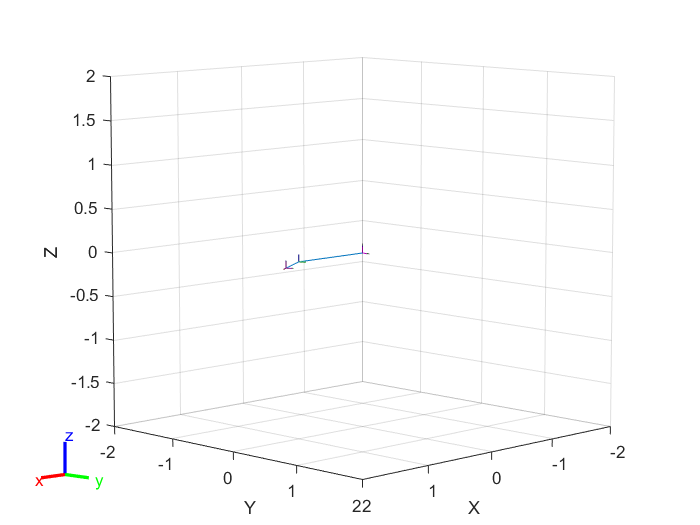

show(robot);

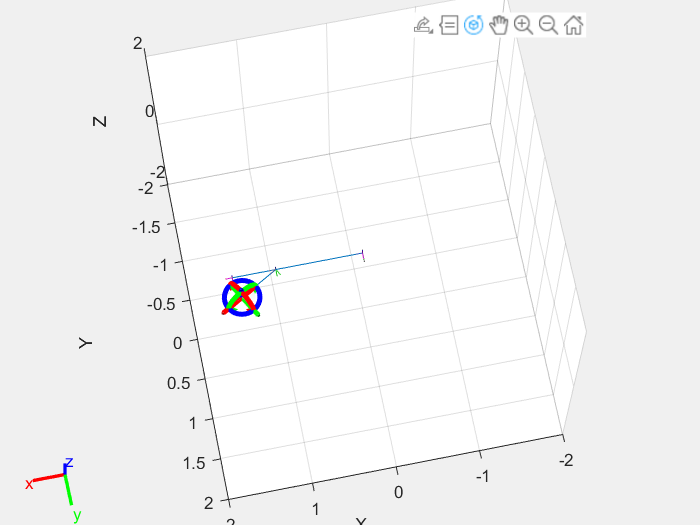

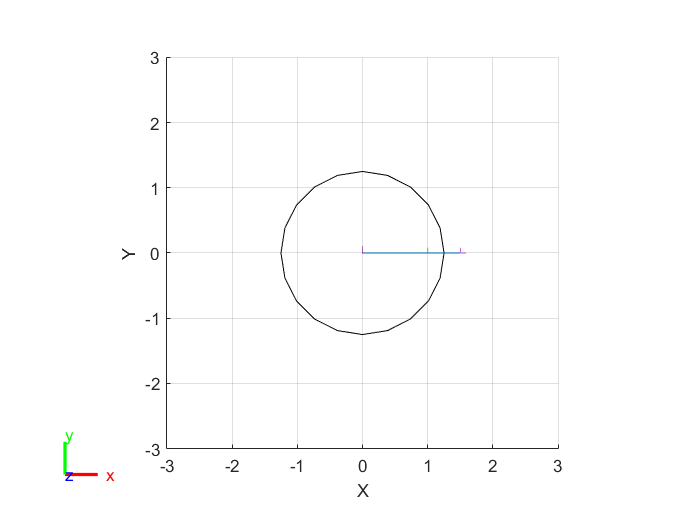


vizztree = interactiveRigidBodyTree(robot);

t = (0:.5:10)'; % Time
count = length(t);
center = [0 0 0];
radius = 1.25;
th = t*(2*pi/t(end));
points = center + radius*[cos(th) sin(th) zeros(size(th))];

q0 = homeConfiguration(robot);
ndof = length(q0);
qs = zeros(count, ndof);

ik = inverseKinematics('RigidBodyTree', robot);
weights = [0, 0, 0, 1, 1, 0];
endEffector = 'endeffector';

qInit = q0; % Use home configuration as the initial guess
for i = 1:count
% Solve for each circle point
point = points(i,:);
qSol = ik(endEffector, trvec2tform(point), weights, qInit);
% Store the configuration
qs(i,:) = qSol;
% Start from prior solution
qInit = qSol;
end

figure
show(robot,qs(1,:)');
% for n = 1:count
% show(robot,qs(n,:)');
% hold on
% end
view(2)
ax = gca;
ax.Projection = 'orthographic';
hold on
plot(points(:,1),points(:,2),'k')
axis([-3 3 -3 3])

framesPerSecond = 15;
r = rateControl(framesPerSecond);
for n = 1:20
for i = 1:count
show(robot,qs(i,:)','PreservePlot',false);
drawnow
waitfor(r);
end
end